# deltaplot examples

deltaplot creates line segments between pairs of values to illustrate the difference between each pair.

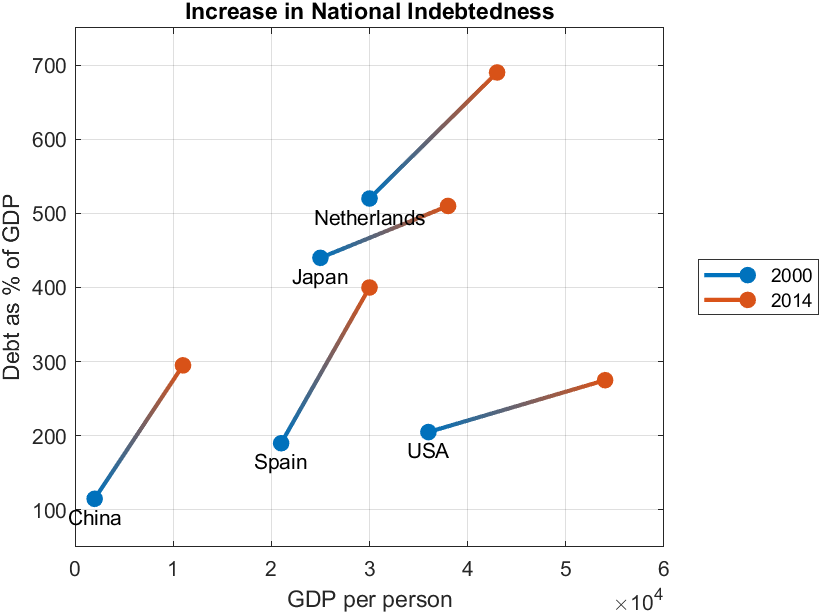

Generate example data representing the number of bicycle journeys each day of the week in 2015 and 2016, in both the eastbound and westbound direction.

[eb_15, wb_15, eb_16, wb_16, daynames] = generateBikeData();

Using deltaplot, we can visualize the number of westbound trips on the x-axis and see how this value compares year over year for each day of the week. 

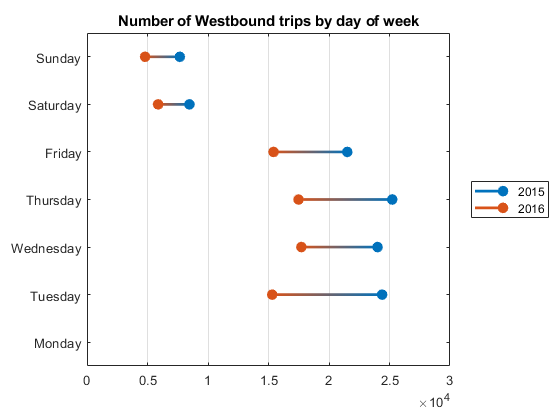

clf
d=deltaplot(wb_15, wb_16, daynames);
d.EndPointLabels = ["2015","2016"];
title('Number of Westbound trips by day of week')

Another way to use deltaplot is to provide both x and y values, for instance the number of eastbound trips on the x-axis and the number of westbound trips on the y-axis.

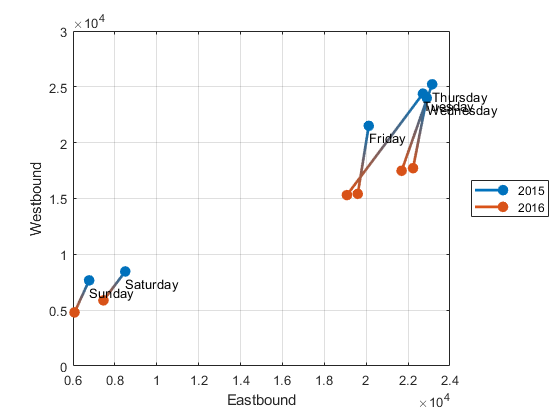

clf
d=deltaplot( eb_15, wb_15, eb_16, wb_16, daynames);
d.EndPointLabels = ["2015","2016"];
ylabel('Westbound')
xlabel('Eastbound')

Provide at least two colors to the ColorOrder property to customize the colors used for the start and end points.

d.ColorOrder = ["g" "m"];

Specify specific xlimits and ylimits.

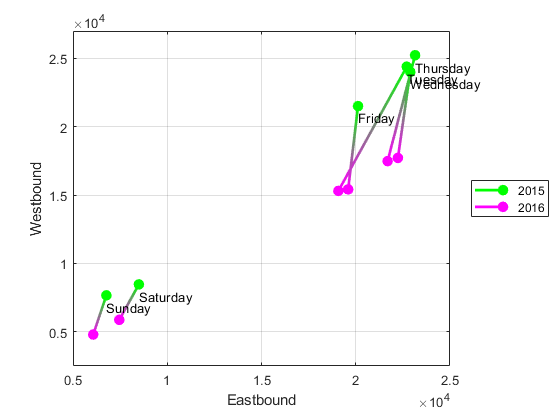

xlim([5000 25000])
ylim([2500 27000])

function [eb_15, wb_15, eb_16, wb_16, daynames] = generateBikeData()
bikeTbl = readtable('BicycleCounts.csv');
bikeTbl.Day = categorical(bikeTbl.Day,["Monday","Tuesday","Wednesday","Thursday","Friday","Saturday","Sunday"]);
bikeTbl = bikeTbl(~isundefined(bikeTbl.Day),:);
daynames = unique(bikeTbl.Day);
bikeTbl15 = bikeTbl(bikeTbl.Timestamp.Year == 2015,:);
bikeTbl16 = bikeTbl(bikeTbl.Timestamp.Year == 2016,:);

wb_15 = splitapply(@sum, bikeTbl15.Westbound,...
                            findgroups(bikeTbl15.Day));
wb_16 = splitapply(@sum,bikeTbl16.Westbound,...
                findgroups(bikeTbl16.Day));
eb_15 = splitapply(@sum, bikeTbl15.Eastbound,...
                            findgroups(bikeTbl15.Day));
eb_16 = splitapply(@sum,bikeTbl16.Eastbound,...
                findgroups(bikeTbl16.Day));
end